## Read and Play Video

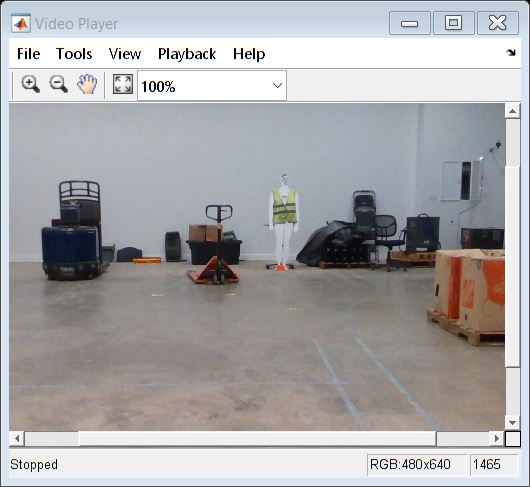

% Read a video file and play it. 
    videoFReader = vision.VideoFileReader('C:\Users\kalyani.chaganti\Downloads\color.avi');
    videoPlayer = vision.VideoPlayer;
    while ~isDone(videoFReader)
      videoFrame = step(videoFReader);
      step(videoPlayer, videoFrame);
    end
    release(videoPlayer);

    release(videoFReader);
   

## Add people detection. Look for a better detector?

%peopleDetector = vision.PeopleDetector
%peopleDetector = peopleDetectorACF('caltech-50x21')
peopleDetector = peopleDetectorACF

peopleDetector =   acfObjectDetector with properties:

             ModelName: 'inria-100x41'
    ObjectTrainingSize: [100 41]
       NumWeakLearners: 2048



% Add a threshold score

% Read a video file and play it. 
    videoFReader = vision.VideoFileReader('C:\Users\kalyani.chaganti\Downloads\color.avi');
    videoPlayer = vision.VideoPlayer;
    while ~isDone(videoFReader)
      I = step(videoFReader);
      %[bboxes,scores] = peopleDetector(I);
      [bboxes,scores] = detect(peopleDetector,I);
      if (~isempty(bboxes))
        I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
      end
      step(videoPlayer, I);
    end
    release(videoPlayer);

    release(videoFReader);
    